A "maneuver profile" is a function F(t, I, T) that outputs the thruster commands for a maneuver. Inputs are t (the time since the start of the maneuver), I (the intensity scaling factor for the whole maneuver output on the interval 0 to 1, and T (the duration of the maneuver).

The output is a structure containing the force command normalized by the maximum thruster force ranging -1 to 1 and the command type, which will be used by commandToPWM to determine which thrusters to fire with the requested intensity. This intensity is first defined as a timeseries on the interval zero to T, then scaled by the total requested maneuver intensity. 

These functions will be called by the parseMissionStruct function. 

function command = forwardProfile(t,I,T)
    %{ 
        In this example the forwardProfile is implimented using a sinusoid
        for a smooth acceleration. The second half of the sinusoid with the
        thrusters firing in reverse is included to bring the vehicle back to
        a stop. Obviously with drag included this profile will need to be
        adjusted to prevent the vehicle from moving backwards.
        
        I recommend tuning your profile on Desmos.com before trying to code it.
    %}

    %this is the line you will change to adjust the maneuver
    local_intensity_t = sin(2*pi/T*t); 

    %scale by the desired maneuver intensity
    intensity_cmd = local_intensity_t*I;

    %set command type
    %{
        This should be constant for a given profile usually, unless the
        maneuver requires you to change which thrusters are firing halfway
        through the maneuver, in which case the command type can be
        implimented as a function of t.
    %}
    type_cmd = "+x";

    %pack up output
    command = {type_cmd,intensity_cmd};


end

Here is an example that shows the profile that will be generated as a function of t.

close all
%create figure in advance to prevent shenanigans
f = figure();



Testing sliders and plot:

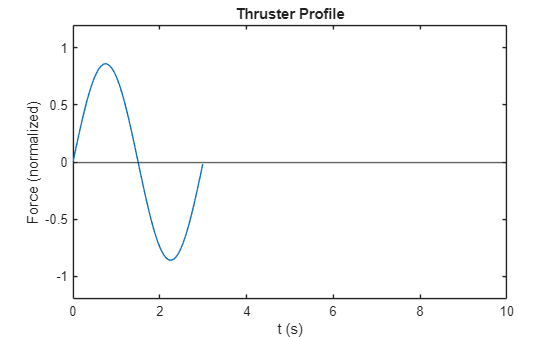


f;
T = 3;
I = 0.86;

step = 0.01;
t = 0:step:(T-step);
cmd_force = zeros([1,length(t)]);

for k = 1:length(t)
    cmd = forwardProfile(t(k),I,T);
    cmd_force(k) = cmd{2};
end

close all

plot(t,cmd_force)
xlim([0,10])
ylim([-1.2,1.2])
xlabel("t (s)")
ylabel("Force (normalized)")
title("Thruster Profile")
yline(0)